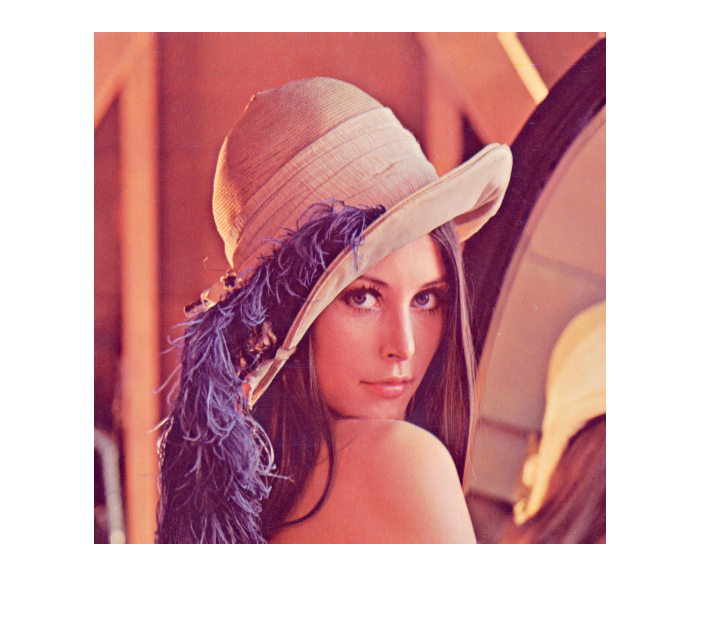

%% data preparation

path = 'C:\Users\fosca\Documents\UNIPD\Magistrale_ICT\Multimedia_Coding\project_repo\MCoding_project\data\';
% path = 'C:\Users\fosca\Documents\UNIPD\Magistrale_ICT\Multimedia_Coding\';
% path = 'C:\Users\fosca\Documents\UNIPD\Magistrale_ICT\Multimedia_Coding\project_repo\MCoding_project\Data_Set\Images\';
A = imread(strcat(path,'lena.tiff'));
% A = imread(strcat(path, 'lena_full.jfif'));
imshow(A)

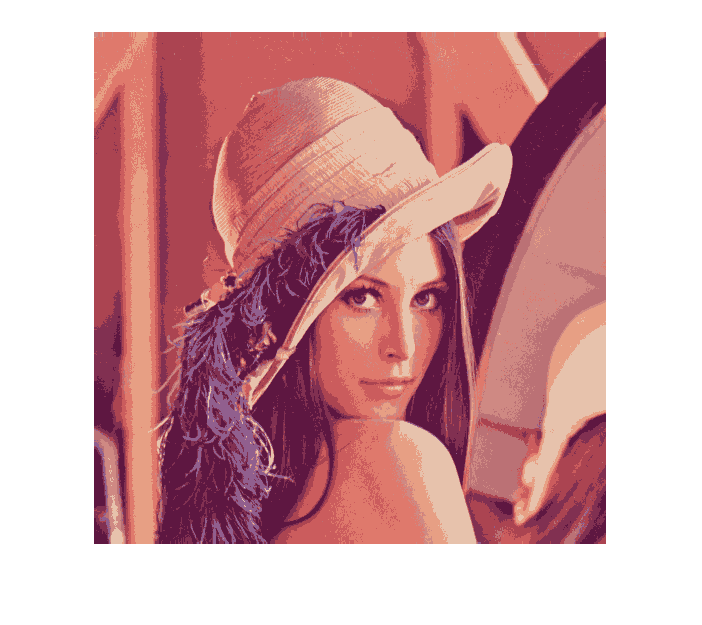

%% Try image with good ol' kmeans first
%reshape image stacking columns
k = 10;
A_r = reshape(A, [],3);
[idx, C] = kmeans(double(A_r), k);
A_k3D = zeros(size(A_r));
C;
% bad implemented with cycles
A_k3D = zeros(size(A_r));
for p = 1:size(idx)
    for i = 1:k
        if idx(p)==i
            A_k3D(p,:) = C(i,:);
        end
    end
end
% % better implementation
% mapfrom = zeros(size(C));
% mapfrom(:,1) = 1:k;
% [sortfrom, sortidx] = sort(mapfrom);
% sortto = C(sortidx);
% A_k3D = zeros(size(A_r));
% A_k3D(:,1) = idx;
% 
% A_k3D = interp1(sortfrom, sortto, A_k3D);


A_k3D = uint8(reshape(A_k3D, size(A)));
imshow(A_k3D)

%implementing my vector quantization